# 2. An equalizer - without buttons

#### 2.1 Bass and treble

The FIR bandpass filter is implemented in the FirBandpass function. The function takes the two cut-off frequencies, the pass-band gain and the length of the filter as arguments. The function is implemented at the bottom of this live script.

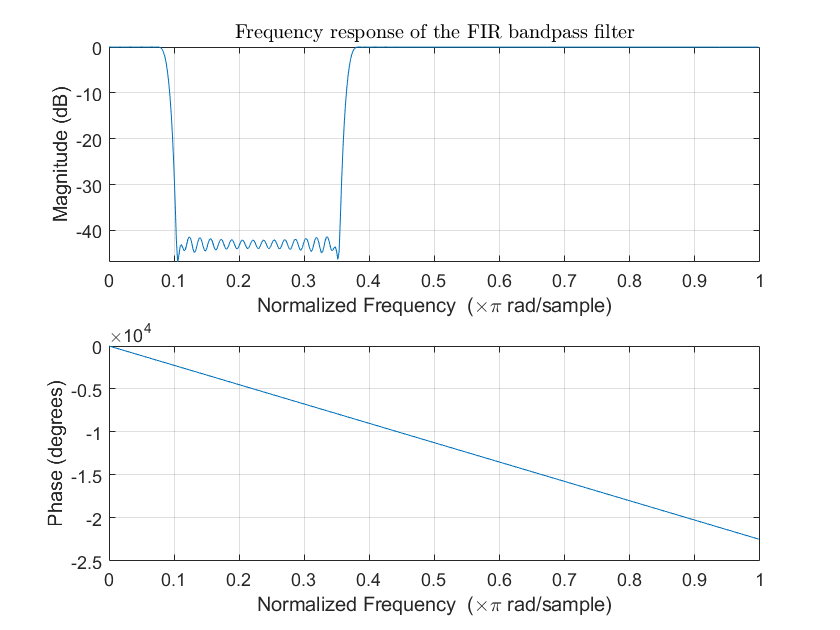

[b,a] = FirBandpass(... 
0.0978,... % lower cutoff frequency
0.3682,... % upper cutoff frequency
  -43,... % pass band gain
  500);   % length of the filter
freqz(b,a); title("Frequency response of the FIR bandpass filter",'Interpreter',"latex")
saveas(gcf,"plots/equalizer.png")

The filter can be applied to music files:

[s,fs] = audioread("scrambled_eggs_5s.wav");

s_f = filter(b,a,s(1:(5*fs))); % filter the signal
s_f_r = 1/max(s_f) * s_f; % normalize the signal
sound(s_f_r,fs)

An attempt of using blockprocessing was made. The implementation uses the filter function which truncates the output signal to the length of the longest input signal. Therefore all overlaps between blocks was ignored. Having overlaps could have been achieved using the conv function instead.

The implementation is furthermore limited by matlabs timing skills. We can not prepare a new buffer while another one is being output since we can not know when it is done

delta_t = 0.2 % time length of a block

delta_t = 0.2000

block_size = fs*delta_t % size of a block in samples

block_size = 8820

blocks = floor(length(s)/block_size) % number of complete blocks

blocks = 25

leftover = mod(length(s),block_size)

leftover = 0

for blocknum = 1:blocks % iterate through all whole blocks
    tic; % start measuring processing time
    [b,a] = FirBandpass(0.3,0.5,-66,240); % create filter parameters
    sub_s = s((blocknum-1)*block_size+1:(blocknum)*block_size-1); % find block
    filtered = filter(b,a,sub_s); % filter block
    pause_t = delta_t - toc;
    pause(pause_t)
    sound(filtered,fs);
end
% play the last block
sub_s = s((blocks)*block_size+1:(blocks)*block_size+leftover);
sound(filter(b,a,sub_s),fs);

function [b,a] = FirBandpass(wc_lwr,wc_upr,G,L)
    % calculate indices
    idx_lwr = fix(wc_lwr*(L/2));
    idx_upr = fix(wc_upr*(L/2));
    
    % synthesize frequency response
    Y = ones(1,ceil((L/2)));
    for i = idx_lwr:idx_upr
        Y(i) = 10^(G/20);
    end
    
    % expand frequency response to the negative frequencies
    if mod(L,2) == 0
        Y = [flip(Y) Y(2:end-1)];
    else
        Y = [flip(Y) Y(2:end)];
    end
    
    % calculate impulse response
    % and rearrange signal to have its peak in the center
    % of the impulse response
    h = fftshift(ifft(ifftshift(Y)));
    
    % how much percent of the IR should be discarded?
    cutfrac = 0.5; 
    
    % create window
    w = hamming(fix(L*(1-cutfrac)))';
    
    % extract part of the impulse response to be windowed
    if mod(L,2) == 0
        sub_h = h(fix(cutfrac*1/2*L):fix(cutfrac*1/2*L)+fix((1-cutfrac)*L)-1);
    else
        sub_h = h(fix(cutfrac*1/2*L):fix(cutfrac*1/2*L)+fix((1-cutfrac)*L)-1);
    end
    
    % apply window
    w_sig = w.*sub_h;
    
    % since we have a FIR filter b=IR
    b=w_sig;
    a=1;
end